# Sample 10-3

## 冗長変換

$\ell_2$ -ノルム最小化

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Redundant transforms

$\ell_2$ -norm minimization

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

### 合成フィルタバンクの大域行列表現

(Global matrix representation of synthesis filter bank)

% # of inputs
nSamples = 4;

% Synthesis filters
f0 = [  1 1 ]/2;
f1 = [ -1 1 ]/2;

% (Circular) convolution matrix
nF = max(length(f0),length(f1));
X = [zeros(nF-1,nSamples-nF+1) eye(nF-1); eye(nSamples)]; % Circular extension matrix
C = [zeros(nSamples,nF-1) eye(nSamples) zeros(nSamples,nF-1)]; % Clipping matrix

% Atoms in (circular) convolution matrix
d0 = C*convmtx(f0.',nSamples+nF-1)*X;
d1 = C*convmtx(f1.',nSamples+1)*X;

辞書 (Dictionary) $\mathbf{D}$

% Dictionary D (Global matrix representation of synthesis filter bank)
D = zeros(nSamples,2*nSamples);
D(:,1:2:end) = d0;
D(:,2:2:end) = d1;
disp(D)

    0.5000   -0.5000         0         0         0         0    0.5000    0.5000
    0.5000    0.5000    0.5000   -0.5000         0         0         0         0
         0         0    0.5000    0.5000    0.5000   -0.5000         0         0
         0         0         0         0    0.5000    0.5000    0.5000   -0.5000



## ムーア・ペンローズ一般逆行列

(Moore-Penrose's inverse)

        
$$\mathbf{T}=\mathbf{D}^T(\mathbf{DD}^T)^{-1}=\mathbf{D}^{+}$$


T = pinv(D); 
disp(T)

    0.5000    0.5000         0         0
   -0.5000    0.5000         0         0
         0    0.5000    0.5000         0
         0   -0.5000    0.5000         0
         0         0    0.5000    0.5000
         0         0   -0.5000    0.5000
    0.5000   -0.0000         0    0.5000
    0.5000   -0.0000         0   -0.5000



### 分析合成処理

(Analysis-synthesis process)

% Signal generation
u = rand(nSamples,1);
disp(u)

    0.8797
    0.8178
    0.2607
    0.5944



% Analysis process
s = T*u;
disp(s)

    0.8487
   -0.0309
    0.5392
   -0.2785
    0.4275
    0.1668
    0.7370
    0.1426



% Energy of subband Coef. vector s
disp(['||s||_2^2 = ' num2str(norm(s,2).^2)])

||s||_2^2 = 1.8638


% Synthesis process
v = D*s;
disp(v)

    0.8797
    0.8178
    0.2607
    0.5944



% MSE evaluation
mymse = @(x,y) mean((x(:)-y(:)).^2);
disp(['MSE = ', num2str(mymse(u, v))]);

MSE = 3.0815e-33


## 他の一般逆行列

(Another pseudo-inverse)

% Coefficients of analysis filters
gamma = -0.5;
delta = 1 - gamma;

% Analysis filters
h0 = [ gamma  delta ];
h1 = [ gamma -delta ];

% (Circular) convolution matrix
nH = max(length(h0),length(h1));
X = [eye(nSamples) ; eye(nH-1) zeros(nH-1,nSamples-nH+1) ]; % Circular extension matrix
C = [zeros(nSamples,nH-1) eye(nSamples) zeros(nSamples,nH-1)]; % Clipping matrix

% Global matrix representation of analysis filter bank
t0 = C*convmtx(h0.',nSamples+1)*X;
t1 = C*convmtx(h1.',nSamples+1)*X;
T = zeros(2*nSamples,nSamples);
T(1:2:end,:) = t0;
T(2:2:end,:) = t1;
disp(T)

    1.5000   -0.5000         0         0
   -1.5000   -0.5000         0         0
         0    1.5000   -0.5000         0
         0   -1.5000   -0.5000         0
         0         0    1.5000   -0.5000
         0         0   -1.5000   -0.5000
   -0.5000         0         0    1.5000
   -0.5000         0         0   -1.5000



% Analysis process
s = T*u;
disp(s)

    0.9106
   -1.7284
    1.0963
   -1.3570
    0.0939
   -0.6883
    0.4517
   -1.3314



% Energy of subband Coef. vector s
disp(['||s||_2^2 = ' num2str(norm(s,2).^2)])

||s||_2^2 = 9.3188


% Synthesis process
v = D*s;
disp(v)

    0.8797
    0.8178
    0.2607
    0.5944



% MSE evaluation
disp(['MSE = ', num2str(mymse(u, v))]);

MSE = 3.8519e-33


### $\gamma$ に対するサブバンド係数のエネルギ変化

(Energy change of sub-band coefficient vector w.r.t. $\gamma$)

% Sweep gamma and evaluate energy of subband coefficient vectors
gammas = linspace(-1.0,2.0,32);
engs = zeros(length(gammas),1);
mses = zeros(length(gammas),1);
for idx = 1:length(gammas)
    % Analysis filters
    gamma = gammas(idx);
    delta = 1 - gamma;
    h0 = [ gamma  delta ];
    h1 = [ gamma -delta ];
    
    % (Circular) convolution matrix
    nH = max(length(h0),length(h1));
    X = [eye(nSamples) ; eye(nH-1) zeros(nH-1,nSamples-nH+1) ]; % Circular extension matrix
    C = [zeros(nSamples,nH-1) eye(nSamples) zeros(nSamples,nH-1)]; % Clipping matrix

    % Global matrix representation of analysis filter bank
    t0 = C*convmtx(h0.',nSamples+1)*X;
    t1 = C*convmtx(h1.',nSamples+1)*X;
    T = zeros(2*nSamples,nSamples);
    T(1:2:end,:) = t0;
    T(2:2:end,:) = t1;

    % Analysis process
    s = T*u;

    % Energy of subband Coef. vector s
    engs(idx) = norm(s,2).^2;
    
    % MSE evaluation
    v = D*s;
    mses(idx) = mymse(u, v);    
end

グラフ描画 (Plot)

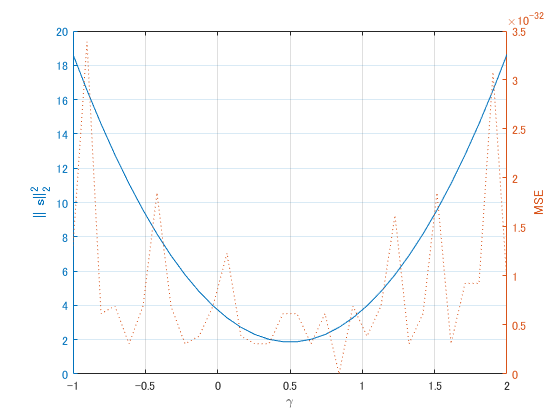

figure(1)
yyaxis left
plot(gammas,engs)
xlabel('\gamma')
ylabel('||{\bf s}||_2^2')
grid on
hold on
yyaxis right
plot(gammas,mses,':')
ylabel('MSE')
hold off

© Copyright, Shogo MURAMATSU, All rights reserved.